# ENME462_Studio2 # MATLAB Basics

by Xie Zheng 

Section 0101 W 1:00PM - 2:50PM

Section 0103 F 10:00AM - 11:50AM

Office Hour: Friday 1:00PM - 2:00PM at 0103 ELG  

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

Email: enme462fall2018@gmail.com

The first objective of this studio is to practice modeling of a pyhsical control system using block diagram. The second objective is to introduce and practice using MATLAB tools for calculating Laplace transforms and their corresponding inverse, transfer functions, and partial fraction expansion.

## Antenna Azimuth Position Control System

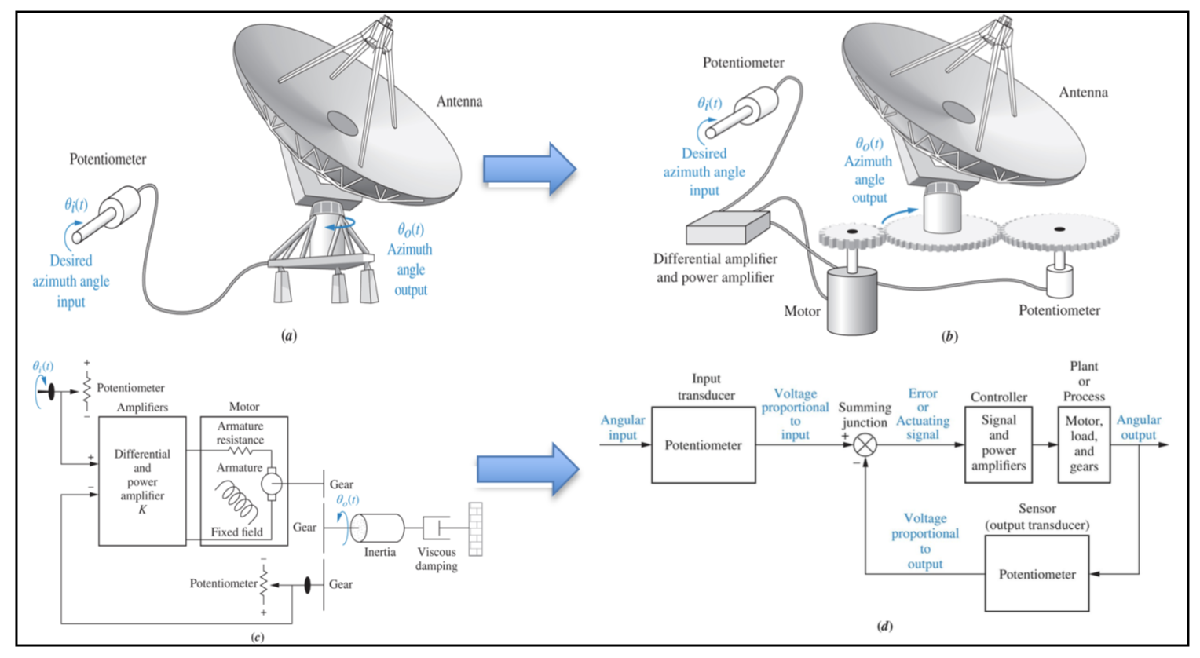

## Constructing transfer functions and partial fractions using MATLAB (This material can be found in APPENDIX B of Nise, 7th Edition) 

**(ch2p2):**Polynomials in ‘s’ can be represented as row vectors containing the

coefficients. For example  $P_1=s^3+7s^2-3s+23$

'(ch2p2)' % Display label.

ans = '(ch2p2)'

P1 = [1 7 -3 23] % Store polynomial s^3 + 7s^2 -3s + 23 as P1 and display.

P1 =      1     7    -3    23


**(ch2p4):** An F(s)  is factored form can be represented in polynomial form. Thus $P_3=(s+2)(s+5)(s+6)$ can be transformed into a polynomial using poly(V), where V is a row vector containing the roots of the polynomial and poly(V) forms the coefficients of the polynomial.

'(ch2p4)' % Display label.

ans = '(ch2p4)'

P3 = poly([-2 -5 -6]) % Store polynomial (s+2)(s+5)(s+6) as P3 and display the coefficients

P3 =      1    13    52    60


**(ch2p5):** We can find roots of polynomials using the roots(V) command. The roots are returned as a column vector. The next example shows how to find the roots of $5s^4+7s^3+9s^2-3s+2=0$

'(ch2p5)' % Display label.

ans = '(ch2p5)'

P4 = [5 7 9 -3 2] % Form 5s^4+7s^3+9s^2-3s+2 and display.

P4 =      5     7     9    -3     2


rootsP4 = roots(P4) % Find roots of 5s^4+7s^3+9s^2 -3s+2, assign to rootsP4, and display.

rootsP4 =   -0.8951 + 1.2351i
  -0.8951 - 1.2351i
   0.1951 + 0.3659i
   0.1951 - 0.3659i


**(ch2p6):** Polynomials can be multiplied together using the conv(a,b) command (standing for convolve). Thus, $P_5=(s^3+7s^2+10s+9)(s^4-3s^3+6s^2+2s+1)$ is calculated as follows:

'(ch2p6)' % Display label.

ans = '(ch2p6)'

P5 = conv([1 7 10 9],[1 -3 6 2 1]) % Form (s^3+7s^2+10s+9)(s^4-3s^3+6s^2+2s+1), assign to P5, and display.

P5 =      1     4    -5    23    48    81    28     9


**(ch2p7):** PFE


$$F(s)=\frac{7s^2+9s+12}{s(s+7)(s^2+10s+100)}\\
PFE=\frac{0.2554-0.3382i}{s+5-8.6603i}+\frac{0.2554+0.3382i}{s+5+8.6603i}-\frac{0.5280}{s+7}+\frac{0.0171}{s}$$



$$\frac{c+di}{s+a+bi}+\frac{c-di}{s+a-bi}\\
=\frac{(c+di)(s+a-bi)}{(s+a+bi)(s+a-bi)}+\frac{(c-di)(s+a+bi)}{(s+a-bi)(s+a+bi)}\\
=\frac{(c+di)(s+a)-bi(c+di)}{(s+a+bi)(s+a-bi)}+\frac{(c-di)(s+a)+bi(c-di)}{(s+a+bi)(s+a-bi)}\\
=\frac{2c(s+a)+2bd}{(s+a)^2+b^2}$$


'(ch2p7)' % Display label.

ans = '(ch2p7)'

numf = [7 9 12]; % Define numerator of F(s).
denf = conv(poly([0 -7]),[1 10 100]); % Define denominator of F(s).
[r,p,k] = residue(numf,denf) % Find residues and assign to K; find roots of denominator and assign

r =    0.2554 - 0.3382i
   0.2554 + 0.3382i
  -0.5280 + 0.0000i
   0.0171 + 0.0000i


p =   -5.0000 + 8.6603i
  -5.0000 - 8.6603i
  -7.0000 + 0.0000i
   0.0000 + 0.0000i



k =

     []



% to p; find constant and assign to

**(ch2p8):** PFE $Y(s)=\frac{32}{s(s^2+12s+32)}=\frac{1}{s+8}-\frac{2}{s+4}+\frac{1}{s}$

'(ch2p8) Example 2.3' % Display label.

ans = '(ch2p8) Example 2.3'

numy = 32; % Define numerator.
deny = [1 12 32 0]; % Define denominator.
[r,p,k] = residue(numy,deny) % Calculate residues, poles, and direct quotient.

r =      1
    -2
     1


p =     -8
    -4
     0



k =

     []



## Modeling tranfsfer function in MATLAB

(1) Vector Method, Polynomial Form

(2) Vector Method, Factored Form

(3) Rational Expression in 's' Method, Polynomial Form

(4) Rational Expression in 's' Method, Factored Form

**(ch2p9):**


$$F(s)=\frac{150(s^2+2s+7)}{s(s^2+5s+4)} \quad
G(s)=\frac{20(s+2)(s+4)}{(s+7)(s+8)(s+9)}$$


'(ch2p9)' % Display label.

ans = '(ch2p9)'


'Vector Method, Polynomial Form' % Display label.

ans = 'Vector Method, Polynomial Form'

numf = 150*[1 2 7] % Store 150(s^2+2s+7) in numf and display.

numf =          150         300        1050


denf = [1 5 4 0] % Store s(s+1)(s+4) in denf and display.

denf =      1     5     4     0


F_VP = tf(numf,denf) % Form F(s) and display.


F_VP =
 
  150 s^2 + 300 s + 1050
  ----------------------
    s^3 + 5 s^2 + 4 s
 
Continuous-time transfer function.




'Vector Method, Factored Form' % Display label.

ans = 'Vector Method, Factored Form'

numg = [-2 -4] % Store (s+2)(s+4) in numg and display.

numg =     -2    -4


deng = [-7 -8 -9] % Store (s+7)(s+8)(s+9) in deng and display.

deng =     -7    -8    -9


K = 20 % Define K.

K = 20

G_VF = zpk(numg,deng,K) % Form G(s) and display.


G_VF =
 
   20 (s+2) (s+4)
  -----------------
  (s+7) (s+8) (s+9)
 
Continuous-time zero/pole/gain model.




'Rational Expression Method, Polynomial Form' % Display label.

ans = 'Rational Expression Method, Polynomial Form'

s = tf('s') % Define 's' as an LTI object in polynomial form.


s =
 
  s
 
Continuous-time transfer function.



F_RP = 150*(s^2+2*s+7)/[s*(s^2+5*s+4)] % Form F(s) as an LTI transfer function in polynomial form.


F_RP =
 
  150 s^2 + 300 s + 1050
  ----------------------
    s^3 + 5 s^2 + 4 s
 
Continuous-time transfer function.



G_RP = 20*(s+2)*(s+4)/[(s+7)*(s+8)*(s+9)] % Form G(s) as an LTI transfer function in polynomial form.


G_RP =
 
     20 s^2 + 120 s + 160
  --------------------------
  s^3 + 24 s^2 + 191 s + 504
 
Continuous-time transfer function.




'Rational Expression Method, Factored Form' %Display label.

ans = 'Rational Expression Method, Factored Form'

s = zpk('s') % Define 's' as an LTI object in factored form.


s =
 
  s
 
Continuous-time zero/pole/gain model.



F_RF = 150*(s^2+2*s+7)/[s*(s^2+5*s+4)] % Form F(s)as an LTI transfer function in factored form.


F_RF =
 
  150 (s^2 + 2s + 7)
  ------------------
    s (s+4) (s+1)
 
Continuous-time zero/pole/gain model.



G_RF = 20*(s+2)*(s+4)/[(s+7)*(s+8)*(s+9)] % Form G(s) as an LTI transfer function in factored form.


G_RF =
 
   20 (s+2) (s+4)
  -----------------
  (s+7) (s+8) (s+9)
 
Continuous-time zero/pole/gain model.



**(ch2p10):**


$$F(s)=\frac{10s^2+40s+60}{s^3+4s^2+5s+7} \quad
G(s)=\frac{10(s+2)(s+4)}{s(s+3)(s+5)}$$


'(ch2p10)' % Display label.

ans = '(ch2p10)'

'Coefficients for F(s)' % Display label.

ans = 'Coefficients for F(s)'

numftf = [10 40 60] % Form numerator of F(s) = (10s^2+40s+60)/(s^3+4s^2+5s+7).

numftf =     10    40    60


denftf = [1 4 5 7] % Form denominator of F(s) = (10s^2+40s+60)/(s^3+4s^2+5s+7).

denftf =      1     4     5     7


'Roots for F(s)' % Display label.

ans = 'Roots for F(s)'

[numfzp,denfzp] = tf2zp(numftf,denftf) % Convert F(s) to factored form.

numfzp =   -2.0000 + 1.4142i
  -2.0000 - 1.4142i


denfzp =   -3.1163 + 0.0000i
  -0.4418 + 1.4321i
  -0.4418 - 1.4321i


'Roots for G(s)' % Display label.

ans = 'Roots for G(s)'

numgzp = [-2 -4] % Form numerator of G(s) = 10(s+2)(s+4)/[s(s+3)(s+5)].

numgzp =     -2    -4


K = 10

K = 10

dengzp = [0 -3 -5] % Form denominator of G(s) = 10(s+2)(s+4)/[s(s+3)(s+5)].

dengzp =      0    -3    -5


'Coefficients for G(s)' % Display label.

ans = 'Coefficients for G(s)'

[numgtf,dengtf] = zp2tf(numgzp',dengzp',K) % Convert G(s) to polynomial form.

numgtf =      0    10    60    80


dengtf =      1     8    15     0


**(ch2p11):**


$$F(s)=\frac{10s^2+40s+60}{s^3+4s^2+5s+7} \quad
G(s)=\frac{10(s+2)(s+4)}{s(s+3)(s+5)}$$


'(ch2p11)' % Display label.

ans = '(ch2p11)'

'Gzpk1(s)' % Display label.

ans = 'Gzpk1(s)'

Gzpk1 = zpk([-2 -4],[0 -3 -5],10) % Form Fzpk1(s)= 10(s+2)(s+4)/[s(s+3)(s+5)].


Gzpk1 =
 
  10 (s+2) (s+4)
  --------------
  s (s+3) (s+5)
 
Continuous-time zero/pole/gain model.



'Gtf1' % Display label.

ans = 'Gtf1'

Gtf1 = tf(Gzpk1) % Convert Fzpk1(s) to coefficients form.


Gtf1 =
 
  10 s^2 + 60 s + 80
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



'Ftf2' % Display label.

ans = 'Ftf2'

Ftf2 = tf([10 40 60],[1 4 5 7]) % Form Ftf2(s)= (10s^2+40s+60)/(s^3+4s^2+5s+7).


Ftf2 =
 
   10 s^2 + 40 s + 60
  ---------------------
  s^3 + 4 s^2 + 5 s + 7
 
Continuous-time transfer function.



'Fzpk2' % Display label.

ans = 'Fzpk2'

Fzpk2 = zpk(Ftf2) % Convert Ftf2(s) to factored form.


Fzpk2 =
 
          10 (s^2 + 4s + 6)
  ---------------------------------
  (s+3.116) (s^2 + 0.8837s + 2.246)
 
Continuous-time zero/pole/gain model.



**(ch2p12):** Functions of time, can be easily plotted using MATLAB's plot(X,Y,S), where X is the independent variable, Y is the dependent variable, and S is a character string describing the plot's color, maker, and line characteristic. Type help plot in the Command Window to see a list of choices for S. Multiple plots also can be obtained using plot(X1,Y1,S1, X2,Y2,S2,X3,Y3,S3,...). In the following example we plot on the same graph sin(5t) in red and cos(5t) in green for t=0 to 10 sec in 0.01 sec increments. Time is specified as follows: t= start:increment:final.

'(ch2p12)' % Display label.

ans = '(ch2p12)'

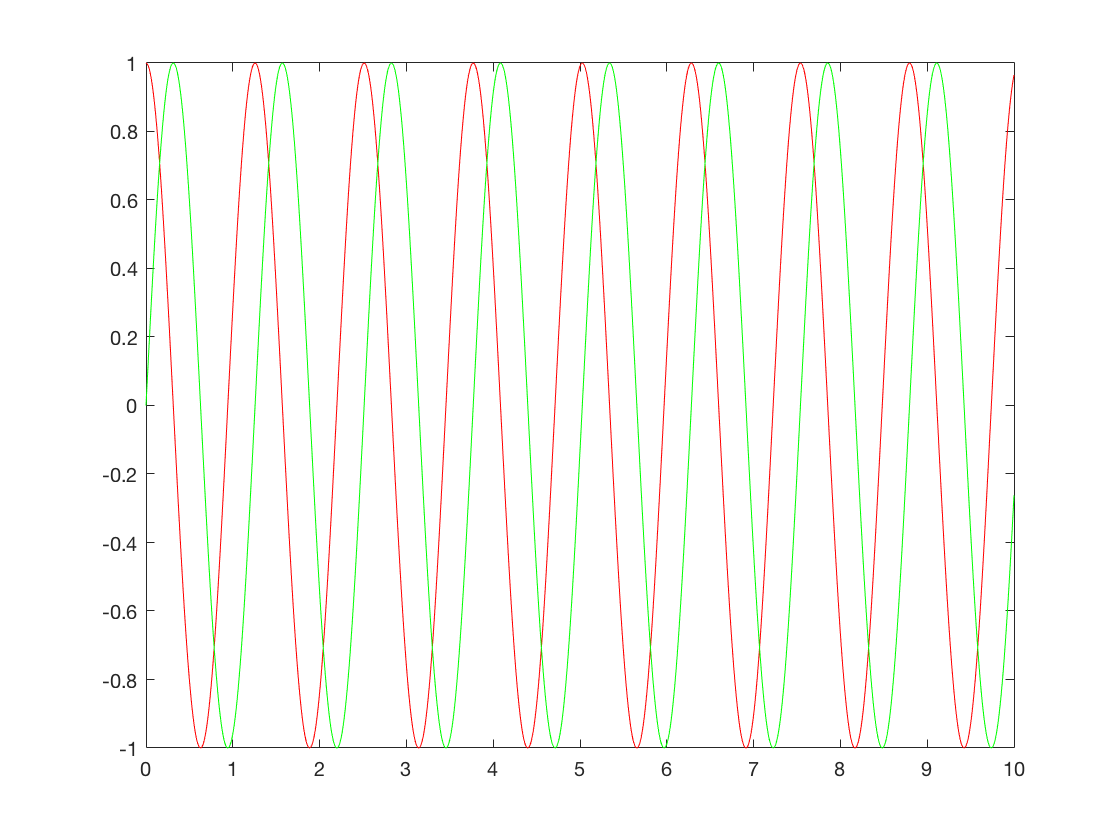

t = 0:0.01:10; % Specify time range and increment.
f1 = cos(5*t); % Specify f1 to be cos(5t).
f2 = sin(5*t); % Specify f2 to be sin(5t)
plot(t,f1,'r',t,f2,'g') % Plot f1 in red and f2 in green.

## Constructiong Transfer Functions, Laplace Transforms, and their inverse using Symbolic Math Toolbox in MATLAB (Appendix F of Nise, 7th Edition)

**(ch2sp1): **


$$F=\frac{2}{(s+1)(s+2)^2} \quad
F=\frac{3}{s(s^2+2s+5)}$$


'(ch2sp1)' % Display label.

ans = '(ch2sp1)'

syms s % Construct symbolic object for Laplace variable 's'.
'Inverse Laplace transform' % Display label.

ans = 'Inverse Laplace transform'

F=2/[(s+1)*(s+2)^2]; % Define F(s) from Case 2 example.
'F(s) from Case 2' % Display label.

ans = 'F(s) from Case 2'

pretty(F) % Pretty print F(s).

        2
----------------
               2
(s + 1) (s + 2)



f=ilaplace(F); % Find inverse Laplace transform.
'f(t) for Case 2' % Display label.

ans = 'f(t) for Case 2'

pretty(f) % Pretty print f(t) for Case 2.

2 exp(-t) - exp(-2 t) 2 - t exp(-2 t) 2



F=3/[s*(s^2+2*s+5)]; % Define F(s) from Case 3 example.
'F(s) for Case 3' % Display label.

ans = 'F(s) for Case 3'

pretty(F) % Pretty print F(s) for Case 3.

        3
----------------
    2
s (s  + 2 s + 5)



f=ilaplace(F); % Find inverse Laplace transform.
'f(t) for Case 3' % Display label.

ans = 'f(t) for Case 3'

pretty(f) % Pretty print f(t) for Case 3.

            /            sin(2 t) \
    exp(-t) | cos(2 t) + -------- | 3
3           \                2    /
- - ---------------------------------
5                   5



**(ch2sp2): **


$$f=2e^{-t}-2te^{-2t}-2e^{-2t} \quad
f=\frac{3}{5}\left[1-e^{-t}\left(\cos(2t)+\frac{1}{2}\sin(2t)\right)\right]$$


'(ch2sp2)' % Display label.

ans = '(ch2sp2)'

syms t % Construct symbolic object for time variable 't'.
'Laplace transform' % Display label.

ans = 'Laplace transform'

'f(t) from Case 2' % Display label.

ans = 'f(t) from Case 2'

f=2*exp(-t)-2*t*exp(-2*t)-2*exp(-2*t); % Define f(t) from Case 2 example.
pretty(f) % Pretty print f(t) from Case 2 example.

2 exp(-t) - exp(-2 t) 2 - t exp(-2 t) 2



'F(s) for Case 2' % Display label.

ans = 'F(s) for Case 2'

F=laplace(f); % Find Laplace transform.
pretty(F) % Pretty print partial fractions of F(s) for Case 2.

  2       2         2
----- - ----- - --------
s + 1   s + 2          2
                (s + 2)



F=simplify(F); % Combine partial fractions.
pretty(F) % Pretty print combined partial fractions.

        2
----------------
               2
(s + 1) (s + 2)



'f(t) for Case 3' % Display label.

ans = 'f(t) for Case 3'

f=3/5-3/5*exp(-t)*[cos(2*t)+(1/2)*sin(2*t)]; % Define f(t) from Case 3 example.
pretty(f) % Pretty print f(t) for Case 3.

            /            sin(2 t) \
    exp(-t) | cos(2 t) + -------- | 3
3           \                2    /
- - ---------------------------------
5                   5



'F(s) for Case 3 - Symbolic fractions' % Display label.

ans = 'F(s) for Case 3 - Symbolic fractions'

F=laplace(f); % Find Laplace transform.
pretty(F) % Pretty print partial fractions of F(s) for Case 3.

 3        3 (s + 1)              3
--- - ---------------- - ----------------
5 s             2                  2
      5 ((s + 1)  + 4)   5 ((s + 1)  + 4)



'F(s) for Case 3 - Decimal representation' % Display label.

ans = 'F(s) for Case 3 - Decimal representation'

F=vpa(F,3); % Convert symbolic numerical fractions to 3-place decimal representation for F(s).
pretty(F) % Pretty print decimal representation.

0.6          0.6           0.6 (s + 1.0)
--- - ---------------- - ----------------
 s             2                  2
      (s + 1.0)  + 4.0   (s + 1.0)  + 4.0



'F(s) for Case 3 - Simplified' % Display label.

ans = 'F(s) for Case 3 - Simplified'

F=simplify(F); % Combine partial fractions.
pretty(F) % Pretty print combined partial fractions.

3.0000000000291038304567337036133
---------------------------------
           2
       s (s  + 2.0 s + 5.0)



**(ch2sp3): **


$$G(s)=\frac{54(s+27)(s^3+52s^2+37s+73)}{s(s^4+872s^3+437s^2+89s+65)(s^2+79s+36)}$$


'(ch2sp3)' % Display label.

ans = '(ch2sp3)'

syms s % Construct symbolic object for frequency variable 's'.
G=54*(s+27)*(s^3+52*s^2+37*s+73)...
/(s*(s^4+872*s^3+437*s^2+89*s+65)*(s^2+79*s+36)); % Form symbolic G(s).
'Symbolic G(s)' % Display label.

ans = 'Symbolic G(s)'

pretty(G) % Pretty print symbolic G(s).

                        3       2
        (54 s + 1458) (s  + 52 s  + 37 s + 73)
-----------------------------------------------------
    2                4        3        2
s (s  + 79 s + 36) (s  + 872 s  + 437 s  + 89 s + 65)



[numg,deng]=numden(G); % Extract symbolic numerator and denominator.
numg=sym2poly(numg); % Form vector for numerator of G(s).
deng=sym2poly(deng); % Form vector for denominator of G(s).
'LTI G(s) in Polynomial Form' % Display label.

ans = 'LTI G(s) in Polynomial Form'

Gtf=tf(numg,deng) % Form and display LTI object for G(s) in polynomial form.


Gtf =
 
            54 s^4 + 4266 s^3 + 77814 s^2 + 57888 s + 106434
  ---------------------------------------------------------------------
  s^7 + 951 s^6 + 69361 s^5 + 66004 s^4 + 22828 s^3 + 8339 s^2 + 2340 s
 
Continuous-time transfer function.



'LTI G(s) in Factored Form' % Display label.

ans = 'LTI G(s) in Factored Form'

Gzpk=zpk(Gtf) % Convert G(s) to factored form.


Gzpk =
 
              54 (s+51.31) (s+27) (s^2 + 0.6934s + 1.423)
  --------------------------------------------------------------------
  s (s+871.5) (s+78.54) (s+0.558) (s+0.4584) (s^2 - 0.05668s + 0.1337)
 
Continuous-time zero/pole/gain model.



## Assignment

1. Use MATLAB to represent and generate the transfer function


$$G(s)=\frac{5(s+15)(s+26)(s+72)}{s(s+55)(s^2+5s+30)(s+56)(s^2+27s+52)}
$$


2. Use MATLAB to generate partial fraction expansion of the following function


$$F(s)=\frac{10^4(s+5)(s+70)}{s(s+45)(s+55)(s^2+7s+110)(s^2+6s+95)}$$


3. Use MATLAB and the SYMBOLIC MATH TOOLBOX to find the Laplace transform of the following functions

(1)$f(t)=8t^2cos(3t+45^o)$

(2)$f(t)=3te^{-2t}sin(4t+60^o)$

4. The forward transfer fucntion of the antenna azimuth position control system is given as 

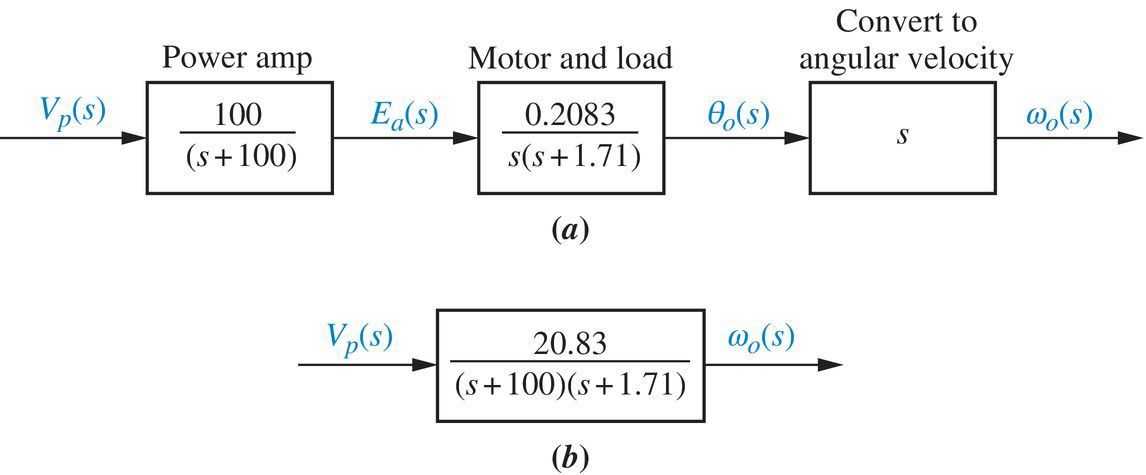

Using MATLAB find and plot the angular velocity response to a unit step input. Hint: use step() in MATLAB.